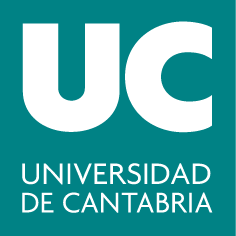

#### ***Grado en Ingeniería ****de Tecnologías de Telecomunicación*

## **G283: Cálculo II**

# **Práctica 5: Integrales de Línea**

*Dpto. Matemática Aplicada y Ciencias de la Computación*

### Objetivos	

- Calcular integrales de línea de campos escalares y usarlas como aplicación del Teorema del Valor Medio sobre alambres.

- Calcular la circulación de un vector alrededor de una curva cerrada y el flujo de un vector que atraviesa una curva, resolviendo las integrales de línea de campos vectoriales.

### Resumen teórico

#### Diferencial de arco

Dada una curva $C$, se llama diferencial de arco a la longitud del arco elemental, que se define como: 

$dl=\sqrt{dx^2+dy^2+dz^2}$ en $\mathbb{R}^3$. 

Si la curva se define en forma paramétrica, tal que $\vec{r}(t)=(x(t), y(t), z(t))$, con $x(t)$, $y(t)$, $z(t)$ derivables con derivada continua, el elemento diferencial de arco es:


$$dl=\sqrt{[x'(t)]^2+[y'(t)]^2+[z'(t)]^2}dt$$


#### Aplicaciones de las integrales de línea de campos escalares


$$\text{Longitud(C)}=\int_{C}dl$$
        
$$\text{Valor medio}=\frac{\int_{C}f(x, y, z) dl}{\text{Longitud(C)}}$$


#### Aplicaciones de las integrales de línea de campos vectoriales

- El **trabajo** realizado por el campo de fuerzas $\vec{F}$ para desplazar una partícula de masa unidad a lo largo de la curva $C$ es la integral de la componente tangencial del campo sobre la curva: 


$$\text{Trabajo}=\int_{C}\vec{F}\cdot\vec{T}dl$$


- La **circulación** es la cantidad total de fluido que rodea una curva cerrada $C$; se calcula con la integral de línea del campo de velocidades, $\vec{V}$, del fluido a lo largo de $C$: 


$$\text{Circulación}=\oint_{C}\vec{V}\cdot\vec{T}dl$$


- El **flujo** es la cantidad de fluido, sujeto al campo de velocidades $\vec{V}$, que atraviesa un elemento unidimensional (un alambre, por ejemplo). Para calcularlo se integra la componente de $\vec{V}$normal a la curva que dibuja el alambre:


$$\text{Flujo}=\int_{C}\vec{V}\cdot\vec{n}dl$$


#### Vectores tangente y normal unitarios


$$\vec{T}=\frac{\frac{dx}{dt}\vec{i}+\frac{dy}{dt}\vec{j}}{\sqrt{\Big(\frac{dx}{dt}\Big)^2+\Big(\frac{dy}{dt}\Big)^2}}$$
        
$$\vec{n}=\frac{\frac{dy}{dt}\vec{i}-\frac{dx}{dt}\vec{j}}{\sqrt{\Big(\frac{dx}{dt}\Big)^2+\Big(\frac{dy}{dt}\Big)^2}}$$


### Comandos útiles

#### Comandos para representar vectores

- `quiver(X, Y, U, V): `Dibuja los vectores escalados de componentes U, V con flechas que tienen su origen en los puntos de coordenadas X, Y. Las matrices X, Y, U, V deben tener el mismo tamaño. Si se añade como quinto argumento 0, los vectores que se representan no se escalan, es decir, la longitud de las flechas es el valor real del módulo de los vectores. Ejemplo:

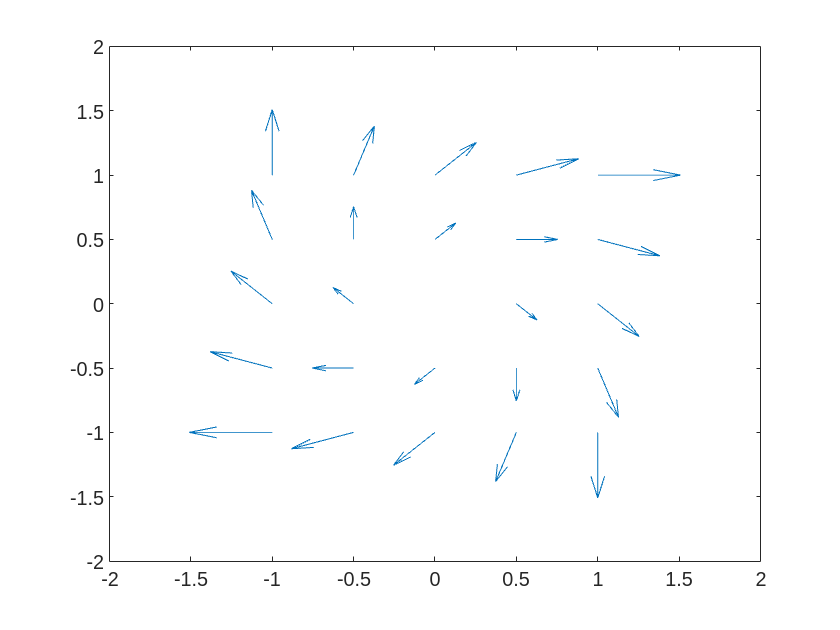

[X,Y]=meshgrid(-1:0.5:1); 
U=Y+X;V=-X+Y; % Componentes del vector 
quiver(X,Y,U,V)

#### Otros comandos para representaciones gráficas

- `plot3(X, Y, Z, S)`: Dibuja las curvas o el conjunto de puntos (X,Y,Z) donde X, Y y Z son vectores fila y S son las opciones de dibujo (este último parámetro se puede ignorar). 

#### Comando para definir las raíces de funciones simbólicamente

- `solve(eq, var)`: Este commando resuelve la ecuación `eq` para la variable `var`, declarando previamente simbólica la variable que interviene. Ejemplo: 

syms x;  raices=solve(x^3-6*x^2+11*x==6,x)

$$raices = \left(\begin{array}{c} 1\\ 2\\ 3 \end{array}\right)$$

Si la ecuación `eq` incluye una función periódica nos da las soluciones solamente en un intervalo de periodicidad. Ejemplo: 

syms x;  raices=solve(sin(x)^2==1,x)

$$raices = \frac{\pi }{2}$$

###  Ejercicios resueltos

**1. [Ejercicio 2.14 del tema] Integral de un campo escalar sobre una curva. Teorema del Valor Medio.**

Un alambre $C$ tiene la forma $x(t)=2cos(t)$, $y(t)=3sen(t)$, $z(t)=4t$, con $t \in \Big[0,\frac{5\pi}{2}\Big]$. Si en cada punto del alambre la temperatura es $T(x,y,z)=x^2$, se pide:

a) Plantear a mano la integral  que da la longitud del alambre y resolverla con Matlab.

b) Calcular la temperatura media del alambre y hallar los puntos donde se alcanza.

c) Representar el alambre destacando los puntos donde se alcanza la temperatura media.

a) Plantear a mano la integral  que da la longitud del alambre y resolverla con Matlab.

El diferencial de arco en $\mathbb{R}^3$ es $dl=\sqrt{[x'(t)]^2+[y'(t)]^2+[z'(t)]^2}dt$

En este caso: $\frac{dx(t)}{dt}=-2sen(t)$, $\frac{dy(t)}{dt}=3cos(t)$, $\frac{d(z(t))}{dt}=4$

Por lo tanto, el diferencial de arco: $dl=\sqrt{4sen^{2}(t)+9cos^{2}(t)+16}dt=\sqrt{4sen^{2}(t)+4cos^{2}(t)+5cos^{2}(t)+16}dt=\sqrt{20+5cos^{2}(t)}dt$

Luego la longitud de la alambre viene dada por la integral: $\displaystyle\int_{0}^{5\pi/2} \sqrt{20+5cos^2(t)}dt$

% Cálculo de la longitud del arco
syms u
L=double(int(sqrt(20+5*(cos(u)^2)),u,0,5*pi/2))

L = 37.2259

b) Calcular la temperatura media del alambre y hallar los puntos donde se alcanza.


$$T(x,y,z)=x^2 \Rightarrow T(t)=4cos^2(t)$$


La temperatura media será: $\text{Tmedia}=\frac{\displaystyle\int_{0}^{5\pi/2} 4cos^2(t)\sqrt{20+5cos^2(t)}dt}{\displaystyle\int_{0}^{5\pi/2} \sqrt{20+5cos^2(t)}dt}$

% Cálculo de la integral de la temperatura T=x^2 a lo largo del arco 
t_promedio=double(int(4*(cos(u))^2*sqrt(20+5*(cos(u)^2)),u,0,5*pi/2))/L

t_promedio = 2.0557

Los puntos donde se alcanza esa temperatura media se pueden calcular resolviendo la ecuación: $4cos^{2}(t)=\text{Tmedia}$

La forma más sencilla para resolver ecuaciones es usando el comand `solve`, sin embargo funciona bien siempre que no contengan funciones periódicas, como en este caso, porque perdemos soluciones.

tm=double(solve(4*(cos(u))^2==t_promedio,u))

tm =     0.7715
   -0.7715


Por trigonometría, habrá cinco soluciones posibles para el parámetro $t$ en el intervalo $t \in \Big[0,\frac{5\pi}{2}\Big]$:

t1=acos(sqrt(t_promedio/4));
t2=pi-t1;
t3=pi+t1;
t4=2*pi-t1;
t5=2*pi+t1;
tm=[t1 t2 t3 t4 t5]

tm =     0.7715    2.3701    3.9131    5.5117    7.0547


c) Representar el alambre destacando los puntos donde se alcanza la temperatura media.

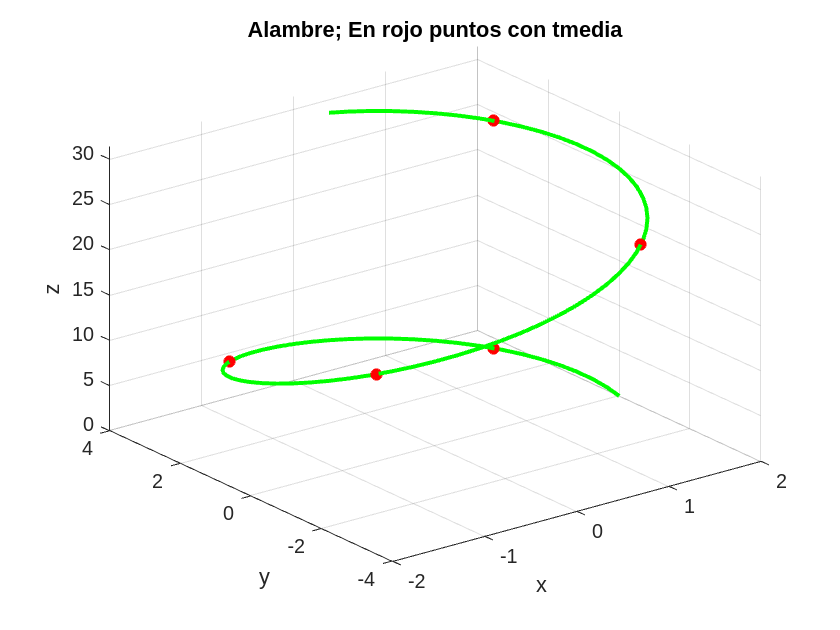

t=0:pi/30:5*pi/2;
 
% Coordenadas x,y,z 
x=2*cos(t);
y=3*sin(t);
z=4*t;
 
% Dibujo del alambre de color verde en la figura 1
figure(1)
plot3(x,y,z,'g','LineWidth',2)
xlabel('x')
ylabel('y')
zlabel('z')
grid on
hold on

%Señala sobre el alambre los puntos donde se alcanza la t_promedio
xm=2*cos(tm);
ym=3*sin(tm);
zm=4*tm;
plot3(xm,ym,zm,'r*','LineWidth',2)

%Pone un título a la figura
title('Alambre; En rojo puntos con tmedia')
hold off

**2. [Ejercicio 2.18 del tema] Cálculo de la circulación de un vector alrededor de una curva cerrada y del flujo del vector a través de la curva**

Sea $\vec{F}(x,y)=(x+1)^2\vec{i}+y\vec{j}$ el campo de velocidades de un fluido y $C$ la circunferencia de radio 1 centrada en el origen.

a) Representa en color negro el campo $\vec{F}$en ocho puntos repartidos uniformemente por la circunferencia. Representa también en los mismos puntos el vector tangente unitario $\vec{T}$en color rojo y el vector normal unitario $\vec{n$ en color verde ¿El fluido tiende a entrar o a salir? ¿El fluido tiende a girar alrededor de $C$en sentido antihorario o en sentido horario?	

b) Calcula el flujo saliente del campo $\vec{F}$hacia fuera de la curva $C$y confirma así la respuesta del primer apartado.	

c) Calcula también el trabajo (o circulación, por ser la curva cerrada) del vector $\vec{F}$al trasladar la unidad de masa por la curva $C$en sentido antihorario y confirma así la respuesta del primer apartado.

a) Representa en color negro el campo $\vec{F}$en ocho puntos repartidos uniformemente por la circunferencia. Representa también en los mismos puntos el vector tangente unitario $\vec{T}$en color rojo y el vector normal unitario $\vec{n$ en color verde ¿El fluido tiende a entrar o a salir? ¿El fluido tiende a girar alrededor de $C$en sentido antihorario o en sentido horario?	

En primer lugar, parametrizamos la circunferencia:

$x(t)=cos(t)$, $y(t)=sen(t)$, con $t\in [0, 2\pi]$

El diferencial de arco es: $dl=\sqrt{[x'(t)]^2+[y'(t)]^2}dt=\sqrt{(-sen(t))^2+(cos(t))^2}dt=dt$


$$\vec{T}=\frac{\frac{dx}{dt}\vec{i}+\frac{dy}{dt}\vec{j}}{\sqrt{\Big(\frac{dx}{dt}\Big)^2+\Big(\frac{dy}{dt}\Big)^2}}=\frac{-sen(t)\vec{i}+cos(t)\vec{j}}{\sqrt{sen^{2}(t)+cos^{2}(t)}}=-sen(t)\vec{i}+cos(t)\vec{j}$$
       

 
$$\vec{n}=\frac{\frac{dy}{dt}\vec{i}-\frac{dx}{dt}\vec{j}}{\sqrt{\Big(\frac{dx}{dt}\Big)^2+\Big(\frac{dy}{dt}\Big)^2}}=\frac{cos(t)\vec{i}+sen(t)\vec{j}}{\sqrt{sen^{2}(t)+cos^{2}(t)}}=cos(t)\vec{i}+sen(t)\vec{j}$$



$$\vec{F}(t)=(cos(t)+1)^2\vec{i}+sen(t)\vec{j}$$


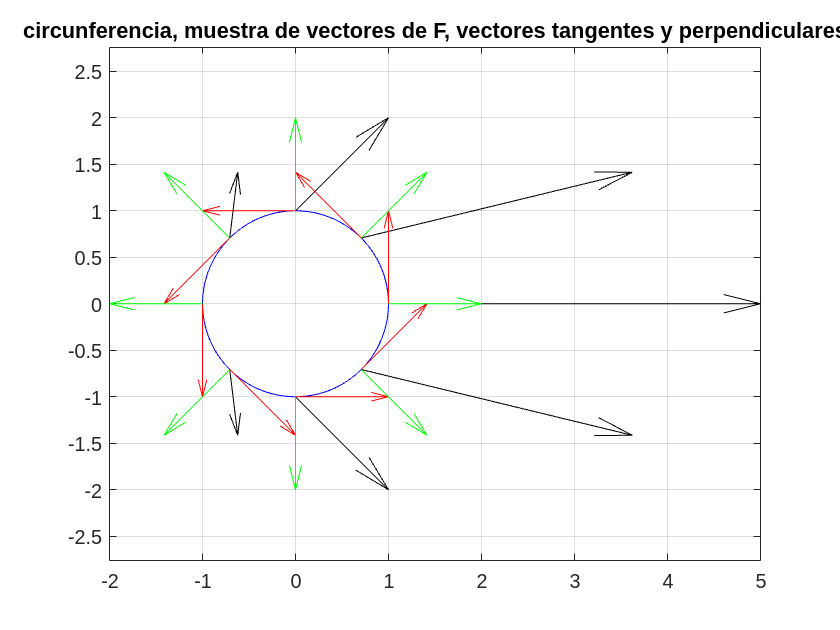

% Dibujamos la circunferencia 
t=linspace(0,2*pi); % vector de parámetros del arco
x= cos(t); % primera componente del arco
y= sin(t); % segunda componente del arco
figure(2)
% Dibujamos el arco en azul con grosor 2 unidades
plot(x,y,'b')
grid on
hold on
% Dibujamos una muestra de 8 vectores del campo vectorial en negro, sin escalar
tv=linspace(0,2*pi,9); 
quiver(cos(tv),sin(tv), (cos(tv)+1).^2,sin(tv),0,'k')
 
% Dibuja sobre la curva los vectores tangentes T en rojo, sin escalar
quiver(cos(tv),sin(tv), -sin(tv),cos(tv),0,'r') 
 
% Dibuja sobre la curva los vectores normales n en verde, sin escalar
quiver(cos(tv),sin(tv),cos(tv), sin(tv),0,'g') 
 
axis equal
title('circunferencia, muestra de vectores de F, vectores tangentes y perpendiculares')
hold off

b) Calcula el flujo saliente del campo $\vec{F}$hacia fuera de la curva $C$y confirma así la respuesta del primer apartado.	


$$\text{Flujo}=\int_{C}\vec{F}\cdot\vec{n}dl=\int_{0}^{2\pi}[(1+cos(t))^2\vec{i}+sen(t)\vec{j}]\cdot(cos(t)\vec{i}+sen(t)\vec{j})dt= \int_{0}^{2\pi}[(1+cos(t))^2 cos(t)+sen^{2}(t)]dt$$


%Calcula el flujo del campo F a través de la curva C
syms u
flujo=int((cos(u)+1)^2*cos(u)+sin(u)*sin(u),u,0,2*pi)

$$flujo = 3\,\pi$$

El flujo es positivo tomando la normal hacia fuera, es decir, el flujo es hacia fuera de la curva (saliente).

c) Calcula también el trabajo (o circulación, por ser la curva cerrada) del vector $\vec{F}$al trasladar la unidad de masa por la curva $C$en sentido antihorario y confirma así la respuesta del primer apartado.


$$\text{Trabajo}=\int_{C}\vec{F}\cdot\vec{T}dl=\int_{0}^{2\pi}[(1+cos(t))^2\vec{i}+sen(t)\vec{j}]\cdot(-sen(t)\vec{i}+cos(t)\vec{j})dt= \int_{0}^{2\pi}[-(1+cos(t))^2 sen(t)+sen(t)cos(t)]dt$$


%Calcula el trabajo del campo F sobre la curva C
trabajo=int((cos(u)+1)^2*(-sin(u))+sin(u)*cos(u),u,0,2*pi)

$$trabajo = 0$$

En la figura se aprecia que $\vec{T}$ va en sentido contrario en la semicircunferencia superior e inferior, por lo tanto, por simetría, se compensan los valores de la integral y resulta ser cero.